# Mecanismo de retorno rápido

## Descrição do Problema

O sistema em questão é um mecanismo de retorno rápido formado por 2 corpos, duas  barras, uma azul com extremidade fixa na origem por uma junta de revolução  e outra amarela com a extremidade fixa em $$[0, d]$$ por uma junta de revolução. Vamos considerar o refenrencial F1 na origem rotacionado de $\theta_1$ e un referencial na posição $$[0, d]$$ rotacionado de $\theta_2$. Por fim as barras estão ligadas entre si por uma uma junta composta.

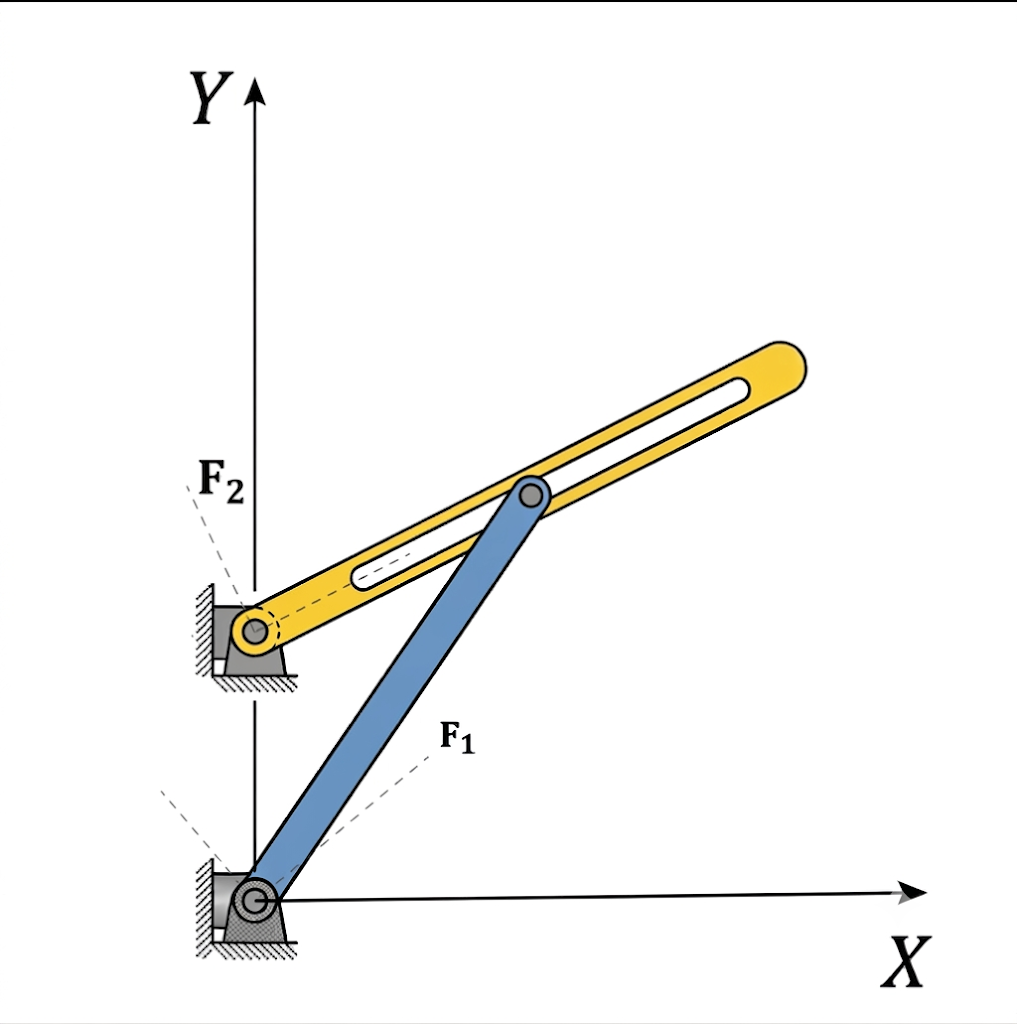

### Primeira junta de revolução


$$\phi_1 = \left[\begin{array}{c} x_1 \\ y_1 \end{array}\right] = \left[\begin{array}{c} 0 \\ 0 \end{array}\right]$$


### Segunda junta de revolução


$$\phi_2 = \left[\begin{array}{c} x_1 \\ y_1 - d \end{array}\right] = \left[\begin{array}{c} 0 \\ 0 \end{array}\right]$$


### Junta composta (revolução - translação)

$\left[\begin{array}{c}
l_1 \cos(\theta_1) \\
l_1 \sin(\theta_1)
\end{array}\right] = \left[\begin{array}{c}
l_2 \cos(\theta_2) \\
l_2 \sin(\theta_2) + d
\end{array}\right]

$  =>  $l_1\sin(\theta_1 - \theta_2) - d\cos(\theta_2) = 0$

### Restrição diretora


$$\phi_d = \theta_1 - \omega t$$


### Definição do sistema

Dessa forma, temos 6 coordenadas generalizadas e 5 equações de restrição cinemática e assim o angulo $\theta_1$ é definido por uma equação de restrição dirigida 


$$\mathbf{q} = \left[\begin{array}{c}
x_1 \\
y_1 \\
\theta_1 \\
x_2 \\
y_2 \\
\theta_2 \\
\end{array}\right];

\phi = \left[\begin{array}{c}
x_1  \\
y_1  \\
x_2 \\
y_2 - d \\
l_1\sin(\theta_1 - \theta_2) - d\cos(\theta_2) \\
\theta_1 -\omega t\\
\end{array}\right] = 0$$


## Definição das variaveis

vamos defnir todas as variaveis necessarias para a solução do problema

### Equação da velocidade


$$\bar{\Phi}_q \cdot \dot{q} = -\bar{\Phi}_t = \nu$$


### Equação da Aceleração


$$\bar{\Phi}_q \cdot \ddot{q} = -(\bar{\Phi}_q \cdot \dot{q})_q \cdot \dot{q} - 2\bar{\Phi}_{qt} \cdot \dot{q} - \bar{\Phi}_{tt} = \gamma$$


% Definindo constantes
l_1 =5;
d = 2;
omega = 1;

% Definindo Funções de restrição
syms x_1 y_1 theta_1 x_2 y_2 theta_2 t dx_1 dy_1 dtheta_1 dx_2 dy_2 dtheta_2

q = [x_1; y_1; theta_1; x_2; y_2; theta_2];
qd = [dx_1; dy_1; dtheta_1; dx_2; dy_2; dtheta_2];

phi = [ x_1;                                         
    y_1;
    x_2;                                         
    y_2 - d;
    l_1*sin(theta_1 - theta_2) - d*cos(theta_2); 
    theta_1 - omega*t ];                         

phi_q = jacobian(phi, q)   

$$phi\_q = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 5\,\cos\left(\theta_{1}-\theta_{2}\right) & 0 & 0 & 2\,\sin\left(\theta_{2}\right)-5\,\cos\left(\theta_{1}-\theta_{2}\right)\\ 0 & 0 & 1 & 0 & 0 & 0 \end{array}\right)$$

phi_t = diff(phi, t)

$$phi\_t = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ -1 \end{array}\right)$$

nu = -phi_t;

phi_qt = diff(phi_q, t)

$$phi\_qt = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

phi_tt = diff(phi_t, t)

$$phi\_tt = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

phi_qq  = jacobian(phi_q * qd, q)

$$phi\_qq = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 5\,{\mathrm{dtheta}}_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)-\sigma_{1} & 0 & 0 & \sigma_{1}-{\mathrm{dtheta}}_{2}\,\left(5\,\sin\left(\theta_{1}-\theta_{2}\right)-2\,\cos\left(\theta_{2}\right)\right)\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=5\,{\mathrm{dtheta}}_{1}\,\sin\left(\theta_{1}-\theta_{2}\right) \end{array}$$

gama = -phi_qq*qd - 2*phi_qt*qd - phi_tt;

% Constantes do Newton-Raphson usadas em todo o código
tol = 1e-10;
N = 50;

% Transformando em matlab funtion
phi   = matlabFunction(phi, 'Vars', {q, t});
phi_q = matlabFunction(phi_q,   'Vars', {q, t});
phi_t = matlabFunction(phi_t,   'Vars', {q, t});
gama  = matlabFunction(gama,  'Vars', {q, qd, t});

## Solução da posição

Parea encontrar o $q_o$ precisamos encontrar as raizes da função $\phi(q,0)$ para isso usaremos o método de Newton-Raphson

t_0 = 0;
q_o = [0; 0; 0; 0; 0; 0]; 
[q_o, iter] = newton_raphson(phi, phi_q, q_o, t_0, tol, N)

q_o =          0
         0
   -0.0000
         0
    2.0000
   -0.3805


iter = 4

## Solução da Velocidade

Derivando $\Phi (q,t) = 0$ no tempo: $\Phi q \cdot  q̇ = -\Phi t = \nu .$ Como $\Phi _q$ já é conhecida (da posição)

nu   = -phi_t(q_o, t_0);
dq_o = phi_q(q_o, t_0) \ nu

dq_o =          0
         0
    1.0000
         0
         0
    0.8621


## Solução da aceleração

Derivando mais uma vez: $\Phi _q \cdot  q̈ = \gamma $. Mesma matriz $\Phi _q$, só muda o lado direito.

gama_o = gama(q_o, dq_o, t_0);
ddq_o  = phi_q(q_o, t_0) \ gama_o

ddq_o =          0
         0
    0.0000
         0
         0
    0.2497


## Próximos passos

Para concluir a análise vamos estimar a posição no instante seguinte partindo da hipótese de aceleração

constante dentro do incremento de tempo.


$$q_{i+1} = q_i + \dot{q}_i \Delta t + \frac{\ddot{q}_i \Delta t^2}{2}$$


%% ---- vetor de tempo ----
dt      = 0.01;
t_final = 4*pi/omega;          
tv      = t_0 : dt : t_final;
n_t     = length(tv);

% alocação
Q   = zeros(6, n_t);
DQ  = zeros(6, n_t);
DDQ = zeros(6, n_t);
IT  = zeros(1, n_t);

q_est = q_o

q_est =          0
         0
   -0.0000
         0
    2.0000
   -0.3805


for i = 1:n_t

    [Q(:,i), IT(i)] = newton_raphson(phi, phi_q, q_est, tv(i), tol, N);

    
    J = phi_q(Q(:,i), tv(i));                    % Jacobiana
    DQ(:,i) = J \ ( -phi_t(Q(:,i), tv(i)) );     % velocidade
    DDQ(:,i) = J \ gama(Q(:,i), DQ(:,i), tv(i)); % aceleração

    q_est = Q(:,i) + DQ(:,i)*dt + DDQ(:,i)*dt^2/2;
end

## Graficos

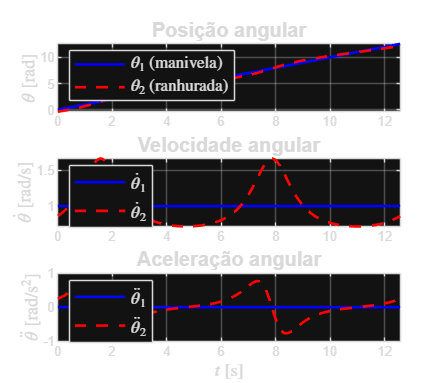

figure('Position',[60 60 900 780],'Color','w');

subplot(3,1,1);
plot(tv, Q(3,:), 'b-', 'LineWidth',1.6); hold on;
plot(tv, Q(6,:), 'r--','LineWidth',1.6); grid on; box on;
ylabel('$\theta$ [rad]','Interpreter','latex','FontSize',11);
legend({'$\theta_1$ (manivela)','$\theta_2$ (ranhurada)'}, ...
    'Interpreter','latex','Location','northwest','FontSize',10);
title('Posição angular','FontSize',12);
xlim([tv(1) tv(end)]);

subplot(3,1,2);
plot(tv, DQ(3,:), 'b-', 'LineWidth',1.6); hold on;
plot(tv, DQ(6,:), 'r--','LineWidth',1.6); grid on; box on;
ylabel('$\dot{\theta}$ [rad/s]','Interpreter','latex','FontSize',11);
legend({'$\dot{\theta}_1$','$\dot{\theta}_2$'}, ...
    'Interpreter','latex','Location','northwest','FontSize',10);
title('Velocidade angular','FontSize',12);
xlim([tv(1) tv(end)]);

subplot(3,1,3);
plot(tv, DDQ(3,:), 'b-', 'LineWidth',1.6); hold on;
plot(tv, DDQ(6,:), 'r--','LineWidth',1.6); grid on; box on;
xlabel('$t$ [s]','Interpreter','latex','FontSize',11);
ylabel('$\ddot{\theta}$ [rad/s$^2$]','Interpreter','latex','FontSize',11);
legend({'$\ddot{\theta}_1$','$\ddot{\theta}_2$'}, ...
    'Interpreter','latex','Location','northwest','FontSize',10);
title('Aceleração angular','FontSize',12);
xlim([tv(1) tv(end)]);

## Funções

function [q, iter] = newton_raphson(f, df, chute, t, tol, n)
    q = chute;
    for iter = 1:n
        F = f(q, t);
        J = df(q, t);
    
    
        dq = -(J \ F);
        q  = q + dq;
    
        if norm(F) < tol && norm(dq) < tol
            return
        end
    end
end